%clear
%animation speed should be pmax*pstep/20fps???? Changed between 1 and 2
%stack, need to fix this, get animations up to 4 stack, and redo NBR with
%lower sample rate to fit animation to 1000 frames
%ALL ANIMATIONS SHOULD FIT 1000 FRAMES FOR EXPORT
clear subplot
sz = size(PosMAT);
len = sz(1,1);
x = PosMAT(:,1);
y = PosMAT(:,2);
u = VelMAT(:,1);
v = VelMAT(:,2);
a = AccMAT(:,1);
b = AccMAT(:,2);
j = JerkMAT(:,1);
k = JerkMAT(:,2);
s = SnapMAT(:,1);
t = SnapMAT(:,2);
nx = cPosMAT(:,1);
ny = cPosMAT(:,2);
nu = cVelMAT(:,1);
nv = cVelMAT(:,2);
na = cAccMAT(:,1);
nb = cAccMAT(:,2);
nj = cJerkMAT(:,1);
nk = cJerkMAT(:,2);
ns = cSnapMAT(:,1);
nt = cSnapMAT(:,2);
%subplot(2,1,1);
plts = cell(2,6);
plts{1,1} = plot(x, y);
hold on
scatter([0;100],[0;100], 'white');
scatter(CP(:,1), CP(:,2), 150, 'X', 'red');
plts{1,2} = quiver(x(1), y(1), u(1), v(1), 0.01, 'green');
plts{1,3} = quiver(x(1), y(1), a(1), b(1), 0.01, 'red');
plts{1,4} = quiver(x(1), y(1), j(1), k(1), 0.01, 'blue');
plts{1,5} = quiver(x(1), y(1), s(1), t(1), 0.01, 'black');
plts{1,6} = plot(0, 0, 'magenta');
scatter(NewTarg(1,1), NewTarg(1,2), 150, 'X', 'magenta');
hold off
%subplot(2,1,2);
interrupt = round(PFact*len)

interrupt = 275

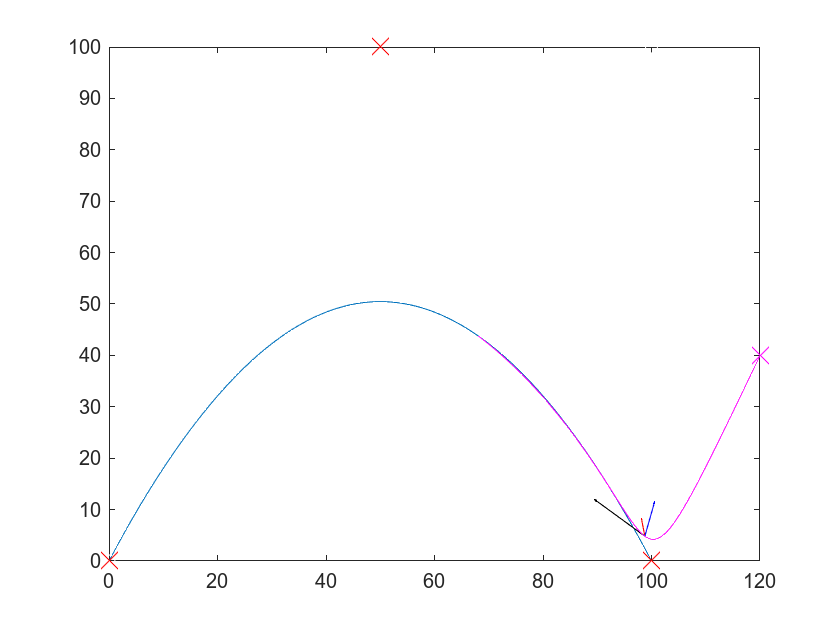

for i = 1:1:interrupt
    %Update graph values
    set(plts{1,2},'XData', x(i), 'YData', y(i), 'UData', u(i), 'VData', v(i));
    set(plts{1,3},'XData', x(i), 'YData', y(i), 'UData', a(i), 'VData', b(i));
    set(plts{1,4},'XData', x(i), 'YData', y(i), 'UData', j(i), 'VData', k(i));
    set(plts{1,5},'XData', x(i), 'YData', y(i), 'UData', s(i), 'VData', t(i));
    %Draw updated graph
    drawnow limitrate;
end
%REPLANNER
nsz = size(cPosMAT);
nlen = nsz(1,1);
set(plts{1,6},'XData', nx, 'YData', ny);
for i = 1:1:nlen
    %Update graph values
    set(plts{1,2},'XData', nx(i), 'YData', ny(i), 'UData', nu(i), 'VData', nv(i));
    set(plts{1,3},'XData', nx(i), 'YData', ny(i), 'UData', na(i), 'VData', nb(i));
    set(plts{1,4},'XData', nx(i), 'YData', ny(i), 'UData', nj(i), 'VData', nk(i));
    set(plts{1,5},'XData', nx(i), 'YData', ny(i), 'UData', ns(i), 'VData', nt(i));
    %Draw updated graph
    drawnow limitrate;
end



scatter([15; -15], [15,; -15], 'white');
hold on
scatter(0,0, 50, 'X','black');
plts{2,2} = quiver(0, 0, u(1), v(1), 0.01, 'green');
plts{2,3} = quiver(0, 0, a(1), b(1), 0.01, 'red');
plts{2,4} = quiver(0, 0, j(1), k(1), 0.01, 'blue');
plts{2,5} = quiver(0, 0, s(1), t(1), 0.01, 'black');
hold off
for i = 1:1:len
    set(plts{2,2},'XData', 0, 'YData', 0,'UData', u(i), 'VData', v(i));
    set(plts{2,3},'XData', 0, 'YData', 0,'UData', a(i), 'VData', b(i));
    set(plts{2,4},'XData', 0, 'YData', 0,'UData', j(i), 'VData', k(i));
    set(plts{2,5},'XData', 0, 'YData', 0,'UData', s(i), 'VData', t(i));
    drawnow limitrate;
end